mat=readtable("stats.csv","VariableNamingRule","preserve");
mat=mat(2:48,:);
data=table2array(mat(:,2:end));
data=data-mean(data);
data=data./std(data);

var=1/47*(data')*data;
[v,d]=eig(var,'vector');
[d,ind]=sort(d,'descend');
v=v(:,ind)

v =     0.5400   -0.1256   -0.4241    0.2383   -0.6753
   -0.5279   -0.2769    0.0054    0.7975   -0.0926
    0.3448    0.0654    0.8846    0.2201   -0.2143
    0.5524   -0.3052   -0.1108    0.3403    0.6882
    0.0753    0.9001   -0.1593    0.3781    0.1262


score=data*v

score =     1.7014    6.1923   -1.3704    1.3126    0.2374
   -0.8357    0.8770    0.1285   -1.3124   -0.6014
   -0.3544    1.2182    0.1250   -1.0787   -0.1843
    0.8920    0.5022    0.2701   -1.4739    0.1323
   -0.3690    1.0498    0.2954   -1.4082   -0.2560
   -0.8749    0.6151    0.3034   -0.7363   -0.4070
   -0.0559    0.7834    0.1303   -0.5054    0.0146
    0.8418   -0.2442    0.0069   -0.2054    0.5469
    1.1879   -0.3493    0.0734   -0.1774    1.3025
    0.1854   -0.0894    0.2723   -0.1946    0.3189


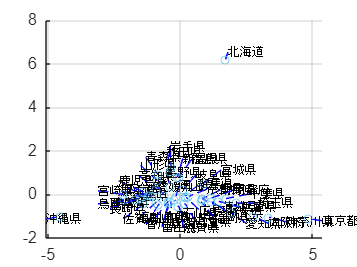


plotData=score(:,1:2);
plotText=mat{:,1};
textPosition=calcTextPosInScatterPlot(plotData);
figure
hold on;
for n1=1:size(plotData,1)
    plot([textPosition(n1,1) plotData(n1,1)],[textPosition(n1,2) plotData(n1,2)],'b--')
    text(textPosition(n1,1), textPosition(n1,2), plotText(n1,:), 1);
end
scatter(plotData(:,1),plotData(:,2));
grid on;
set(gca,'FontName','arial','FontSize',12)

hold off;

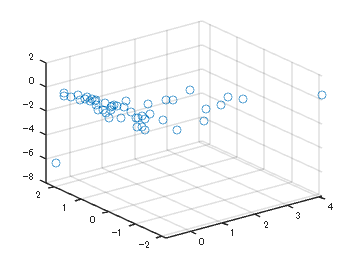

scatter3(data(:,1),data(:,2),data(:,3));


cumsum(d)*100/sum(d)

ans =    48.7480
   71.1780
   88.5097
   95.8359
  100.0000
